# Ecuaciones lineales de primer orden  

# Problemas de valor inicial

#### Use separation of variables to find solutions of the IVP given by y(0) = 1 and the following differential equations:

(a)$\frac{\mathrm{d}}{\mathrm{d}t}y=t$    (b) $\frac{\mathrm{d}}{\mathrm{d}t}y=t^2 y$    (c) $\frac{\mathrm{d}}{\mathrm{d}t}y=2\left(t+1\right)y\;$

% t en [0,2]

### Resuelve numéricamente los siguientes problemas.

Compara en una gráfica las soluciones obtenidas por diferentes métodos.


$$y^{\prime } =y\left(1-y\right)$$
      
$$y\left(0\right)=1/2$$


% t en [0,6]
% f = @(t,y) y*(1-y)


$$y^{\prime } =k{\left(a_0 -y\right)}^2 \left(b_0 -y/2\right)$$
     
$$y\left(0\right)=0$$


$k=0\ldotp 00713$; $a_0 =4$; $b_0 =1$

% t en [0,400]

Resuelve el siguiente problema de valor inicial en el intervalo de $t=0$ a $t=2$


$$y^{\prime } =yt^2 -1\ldotp 1y$$
      
$$y\left(0\right)=1$$


% Solucion analitica
syms y(t) 
eqn = diff(y,t) == y*t^2 - 1.1*y;
yG = dsolve(eqn)

$$yG = C_{1}\,{\mathrm{e}}^{\frac{t\,\left(10\,t^{2}-33\right)}{30}}$$

cond = y(0) == 1;
yP = dsolve(eqn,cond)

$$yP = {\mathrm{e}}^{\frac{t\,\left(10\,t^{2}-33\right)}{30}}$$

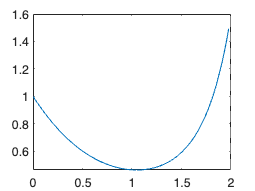

fplot(yP, [0 2]);

Si se drena el agua desde un tanque cilindrico vertical abriendo una válvula en la base, el líquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$y^{\prime } =-k\sqrt{y}$           (*y* en metros y *t* en minutos)

donde *k* es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero.

¿En cuántos minutos se vaciará un tanque que inicialmente tiene 3 metros de agua? (k = 0.06)

f=@(y,k) 1/(-k*sqrt(y));
y0=0;
t0=0;
tf=3;
h = 0.06;
[t,y4] = odeRK4(f,t0,y0,tf,h)

t =          0    0.0600    0.1200    0.1800    0.2400    0.3000    0.3600    0.4200    0.4800    0.5400    0.6000    0.6600    0.7200    0.7800    0.8400    0.9000    0.9600    1.0200    1.0800    1.1400    1.2000    1.2600    1.3200    1.3800    1.4400    1.5000    1.5600    1.6200    1.6800    1.7400    1.8000    1.8600    1.9200    1.9800    2.0400    2.1000    2.1600    2.2200    2.2800    2.3400    2.4000    2.4600    2.5200    2.5800    2.6400    2.7000    2.7600    2.8200    2.8800    2.9400


y4 =      0  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf  -Inf


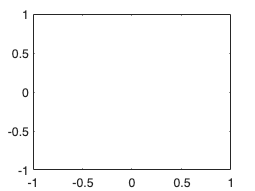

plot(t,y4)

Para simular la dinámica de una poblacion se utiliza el modelo logistico:


$$p^{\prime } =k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde *p *es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y$p_{\max }$es la capacidad de carga. Simula la población mundial entre 1950 y 2022, sabiendo que en 1950 había 2555 millones de personas. Para la simulación utiliza los siguientes valores de parametros: $k_{\textrm{gm}} =0\ldotp 026/\textrm{año}$ y $p_{\max } =12000$ millones de personas-

¿Cuántos millones de personas habrá en 2022?

%

More examples

% y' = f
% y(0) = 1; 0 <=t<= 10;
% f         Exact solution
% 0         1
% t         1+t^2/2
% y         exp(t)
% -y        exp(-t)
% 2*y-y^2   2/(1+exp(-2*t))

function [t,y]=odeRK4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    m=length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end